# Gabriel Colangelo

clear
close all
clc

## Problem 3a) Hohmann Transfer from Earth to Mars

Find: Time of flight and synodic period

Assume: Circular, coplanar orbits. Mass of Earth/Mars negligble during transfer arc.

% Sun properties
mu_sun      = 132712440017.99;

% Periapsis distance - Sun to Earth
rp          = 149597898;

% Apoapsis distance - Sun to Mars
ra          = 227944135;

% Semi major axis of hohmann arc
a_hohmann   = (ra + rp)/2;

% Period of hohmann transfer ellipse
tau_hohmann = 2*pi*sqrt(a_hohmann^3/mu_sun);

% Hohmann time of flight
TOF_hohmann = tau_hohmann/2;
fprintf('The Hohmann transfer time of flight from Earth to Mars is %.2f days',TOF_hohmann/(24*3600))

The Hohmann transfer time of flight from Earth to Mars is 258.87 days


$$r_a = r_{sun,mars}\\
r_p = r_{sun,earth}\\
a = (r_a + r_p)/2\\
Period = 2\pi\sqrt{\frac{a^3}{\mu_{sun}}\\
TOF_{hoh} = Period/2\\
\\
TOF_{hoh} = 258.87 \ [days]$$


% Mean motion of Earth about sun
n_earth     = sqrt(mu_sun/rp^3);

% Mean motion of Mars about sun
n_mars      = sqrt(mu_sun/ra^3);

% Synodic period
ts          = 2*pi/(n_earth - n_mars);
fprintf('The synodic period is %.2f days',ts/(24*3600));

The synodic period is 779.92 days


$$n_{earth} = \sqrt{\frac{\mu_{sun}}{r_p^3}}\\
n_{mars} = \sqrt{\frac{\mu_{sun}}{r_a^3}}\\
\text{Synodic period} = \frac{2\pi}{n_{earth} - n_{mars}}\\
\\
\text{Synodic period} = 779.92 \ [days] = 2.135 \ [\text{Julian Years}]$$


## Problem 3b) Minimum Energy Transfer, transfer angle of 130 deg

$\underline{Find}: a, e, p, r_a, r_p, TOF, v_D, \gamma_D, \theta^*_D, v_A,\gamma_A, \theta^*_A, energy$ for minimum energy transfer

% Position 1 distance - Sun to Earth
r1      = 149597898;

% Position 2 distance - Sun to Mars
r2      = 227944135;

% TA 130 = phi
phi     = 130; 

% Chord, law of cosines
c       = sqrt(r1^2 + r2^2 - 2*r1*r2*cosd(phi));

% Minimum semi major axis
a_m     = (r1 + r2 + c)/4;
fprintf('The minimum energy semi major axis is %.4E km',a_m)

The minimum energy semi major axis is 1.8033E+08 km


$$r_2 = r_{sun,mars}\\
r_1 = r_{sun,earth}\\
\phi = TA = 130 \ [deg]\\
\text{Law of cosines from space triangle: } \ c^2 = r_1^2 + r_2^2 - 2r_1r_2\cos{\phi} \\
\text{Minimum energy semi-perimeter: } \ 4a_m = r_1 + r_2 + c\\
\\
a_m = 1.8033 \times 10^8 \ [km]$$


% Law of sines
x       = asind(r1*sind(phi)/c);

% Law of cosines
OF      = sqrt(r2^2 + (2*a_m - r2)^2 -(2*r2*(2*a_m-r2)*cosd(x)));

% Solve for eccentricity
e_m     = OF/(2*a_m);
fprintf('The minimum energy ellipse eccentricity is %.3f',e_m)

The minimum energy ellipse eccentricity is 0.310


$$\text{Law of sines from space triangle: } \ \frac{c}{\sin{\phi}} = \frac{r_1}{\sin{x}}\\
\text{Law of cosines from space triangle: } \ OF^2 = r_2^2 + (2a_m - r_2)^2 - 2r_2(2a_m - r_2)\cos{x} \\
OF = 2a_me_m \\
\\
e_m = 0.310$$


% Semi-latus rectrum
p_m     = a_m*(1 - e_m^2);
fprintf('The minimum energy semi latus rectum is %.4E km',p_m)

The minimum energy semi latus rectum is 1.6296E+08 km


$$p_m = a_m(1 - e_m^2) \\
p_m = 1.6296 \times 10^8 \ [km]$$


% Periapsis distance for minimum energy ellipse
rp_m     = a_m*(1 - e_m);
fprintf('The periapsis distance for the minimum energy ellipse is %.4E km', rp_m);

The periapsis distance for the minimum energy ellipse is 1.2436E+08 km


$$r_p = a_m(1-e_m) \\
r_p = 1.2436 \times 10^8\ [km]$$


% Apoapsis distance for minimum energy ellipse
ra_m     = a_m*(1 + e_m);
fprintf('The apoapsis distance for the minimum energy ellipse is %.4E km', ra_m);

The apoapsis distance for the minimum energy ellipse is 2.3630E+08 km


$$r_p = a_m(1-e_m) \\
r_p = 2.3630 \times 10^8\ [km]$$


% Calculate energy of transfer ellipse
energy_m = -mu_sun/(2*a_m);
fprintf('The specific energy for the transfer is %.2f km^2/s^2',energy_m)

The specific energy for the transfer is -367.98 km^2/s^2


$$energy = \frac{-\mu}{2a_m} \\
energy = -367.98 \ [km^2/s^2]$$


% Calculate true anomaly at departure
theta_D = acosd((p_m/r1 - 1)/e_m);

% Calculate true anomaly at arrival
theta_A = -acosd((p_m/r2 - 1)/e_m);


$$\theta^* = \cos^{-1}{(\frac{1}{e_m}(\frac{p}{r} - 1))} \\
\theta^*_D = \pm 73.28 \ [deg] \\
\theta^*_A = \pm 156.72 \ [deg] \\
\text{4 possible combinations of $\theta^*_1$ and $\theta^*_2$. However, only one pair produces a transfer angle of 130 deg.}\\
\text{Therefore, the pair of true anomaly's must be:} \\
\\
\theta^*_D = 73.28 \ [deg] \\
\theta^*_A = -156.72 \ [deg]  = 203.28 \ [deg] \\$$


% Velocity magnitude at departure
v_D         = sqrt(2*(energy_m + mu_sun/r1));
fprintf('The heliocentric velocity magnitude at departure on the minimum energy transfer ellipse is %.3f km/s',v_D)

The heliocentric velocity magnitude at departure on the minimum energy transfer ellipse is 32.223 km/s


$$v_D = \sqrt{2(\frac{\mu}{r_1} - \frac{\mu}{2 a_m})}\\
v_D = 32.223 \ [km/s]$$


% Heliocentric Velocity magnitude at arrival
v_A         = sqrt(2*(energy_m + mu_sun/r2));
fprintf('The heliocentric velocity magnitude at arrival on the minimum energy transfer ellipse is %.3f km/s',v_A)

The heliocentric velocity magnitude at arrival on the minimum energy transfer ellipse is 20.700 km/s


$$v_A = \sqrt{2(\frac{\mu}{r_2} - \frac{\mu}{2 a_m})}\\
v_A = 20.7 \ [km/s]$$


% Minimum energy transfer specific angular momentum
h_m         = sqrt(mu_sun*p_m);

% Flight path angle at departure
gamma_D     = sign(theta_D)*acosd(h_m/(r1*v_D));
fprintf('The flight path angle at departure is %.3f deg',gamma_D)

The flight path angle at departure is 15.264 deg


$$h = \sqrt{\mu p}\\
h = r_1v_D\cos{\gamma_D}\\
\\
\gamma_D = 15.264 \ [deg] \ \ \text{ascending based on $\theta^*_D$, so $\gamma$ > 0}$$


% Flight path angle at arrival
gamma_A     = sign(theta_A)*acosd(h_m/(r2*v_A));
fprintf('The flight path angle at arrival is %.3f deg',gamma_A)

The flight path angle at arrival is -9.736 deg


$$h = \sqrt{\mu p}\\
h = r_2v_A\cos{\gamma_A}\\
\\
\gamma_A = -9.736 \ [deg] \ \ \text{descending based on $\theta^*_A$, so $\gamma$ < 0}$$


% Calculate eccentric anomaly at arrival and departure
E_A     = wrapTo2Pi(2*atan(tand(theta_A/2)/sqrt((1+e_m)/(1-e_m))));
E_D     = 2*atan(tand(theta_D/2)/sqrt((1+e_m)/(1-e_m)));

% Calculate Mean Anomaly at arrival and 
M_A     = E_A - e_m*sin(E_A);
M_D     = E_D - e_m*sin(E_D);

% Mean motion of transfer arc
n       = sqrt(mu_sun/a_m^3);

% Time of flight
TOF_min = (M_A - M_D)/n;
fprintf('The time of flight for the minimum energy transfer is %.2f days',TOF_min/(24*3600));

The time of flight for the minimum energy transfer is 240.64 days


$$\tan({\frac{\theta^*}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E}{2}) \\

E = 2\tan^{-1}{[\tan({\frac{\theta^*}{2}) /\sqrt{\frac{1+e}{1-e}} ]} \\
M = E - e_m\sin{E} \\
M_A =  M_D + \sqrt{\frac{\mu}{a_m^3}}(t_A - t_D) \\
(t_A - t_D) = TOF =  \frac{M_A - M_D}{ \sqrt{\frac{\mu}{a_m^3}}} \\
\\
TOF_{min} = 240.64 \ [days] $$


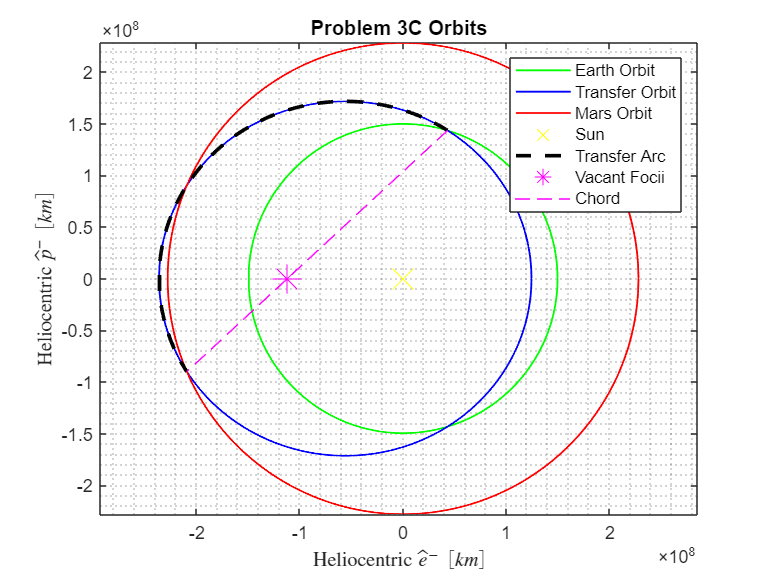

% True anomaly vector
ta_vec          = 0:.001:360;

% Initialize position vectors
r_P_earth       = zeros(2,length(ta_vec)); 
r_P_mars        = r_P_earth;              
r_P_transfer    = r_P_earth;         

for i = 1:length(ta_vec)

    % Calculate old orbit radii
    r_m             = p_m/(1 + e_m*cosd(ta_vec(i)));

    % DCM matrix from rotating orbit frame to perifocal frame
    P_DCM_R         = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                           sind(ta_vec(i)), cosd(ta_vec(i))];

    % Rotate transfer orbit from orbit frame to perifocal frame
    r_P_transfer(:,i)  = P_DCM_R*[r_m;0];

    % Rotate earth orbit position vector from orbit frame to perifocal frame
    r_P_earth(:,i)  = P_DCM_R*[r1;0];

    % Rotate mars orbit position vector from orbit frame to perifocal frame
    r_P_mars(:,i)   = P_DCM_R*[r2;0];
        
end

% Indices of transfer arc
ind_transfer = find(ta_vec > theta_D & ta_vec < (theta_A +360));

% Get position vector from r2 to vacant focii in perifocal coordinates
dF           = [cosd(theta_A+180), -sind(theta_A+180);...
                sind(theta_A+180), cosd(theta_A+180)]*([cosd(x);sind(x)]*(2*a_m-r2));

figure
plot(r_P_earth(1,:), r_P_earth(2,:),'-g','LineWidth',1)
hold on
plot(r_P_transfer(1,:), r_P_transfer(2,:),'-b','LineWidth',1)
plot(r_P_mars(1,:), r_P_mars(2,:),'-r','LineWidth',1)
plot(0, 0,'yx','MarkerSize',16)
plot(r_P_transfer(1,ind_transfer),r_P_transfer(2,ind_transfer),'--k','LineWidth',2)
plot(r_P_transfer(1,ind_transfer(end)) + dF(1),r_P_transfer(2,ind_transfer(end)) + dF(2),'*m','MarkerSize',16)
plot([r_P_transfer(1,ind_transfer(1)),r_P_transfer(1,ind_transfer(end))],...
    [r_P_transfer(2,ind_transfer(1)),r_P_transfer(2,ind_transfer(end))],'--m')
grid minor
xlabel('Heliocentric $\hat{e}^- \ [km]$', 'Interpreter','latex')
ylabel('Heliocentric $\hat{p}^- \ [km]$', 'Interpreter','latex')
axis equal
title('Problem 3C Orbits')
legend('Earth Orbit','Transfer Orbit','Mars Orbit','Sun','Transfer Arc',...
       'Vacant Focii','Chord')

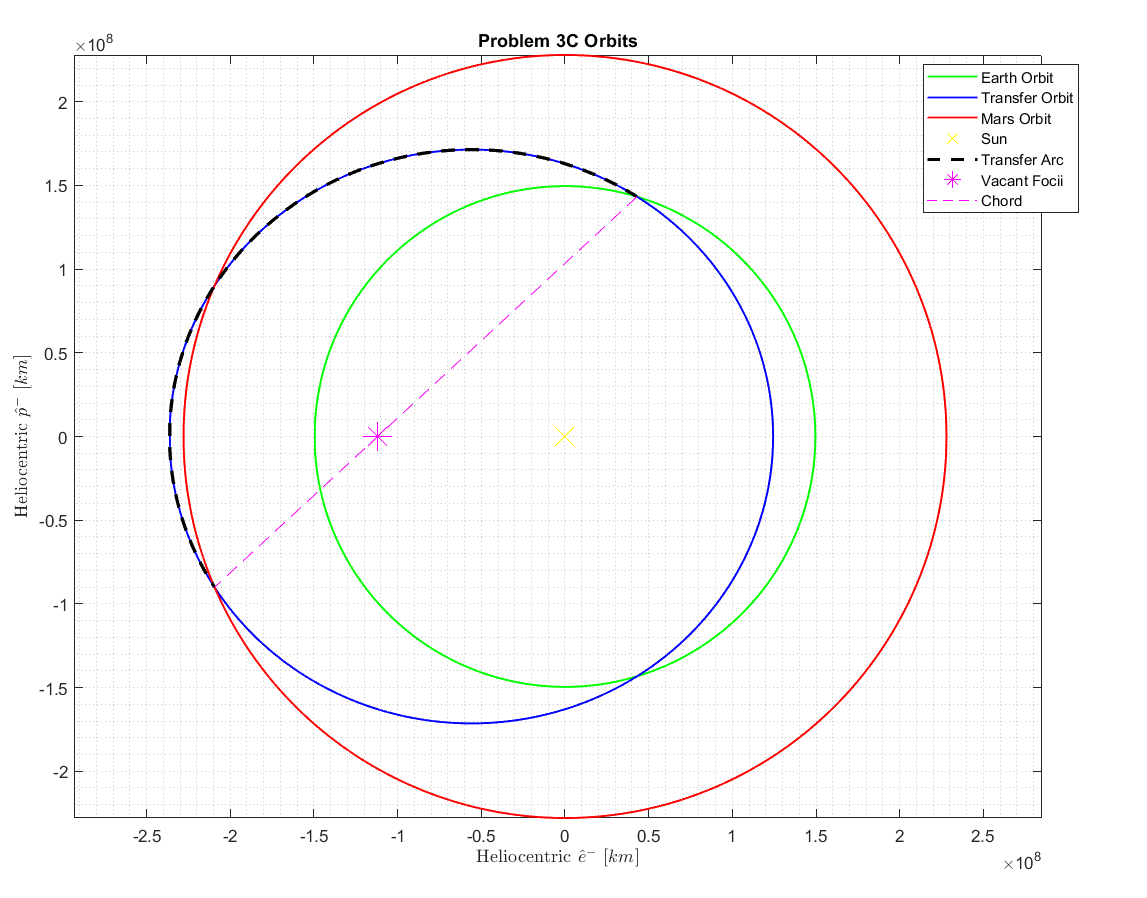

## Problem 3c)

Find: Phase angle required at departure and when the geometry appear again

% Calculate phase angle of space station at depature
phase_min   = (130*pi/180 - n_mars*TOF_min)*180/pi;
fprintf('The phase angle at departure for the minimum energy transfer is %.2f deg',phase_min)

The phase angle at departure for the minimum energy transfer is 3.90 deg


$$(n_{mars})(TOF_{min}) = 130 - \phi \\
\\
\phi = 3.90 \ [deg] \ \ \ \text{Phase angle at departure}$$


**This geometry will reappear after the synodic period of 779.9 days.**

## Problem 3d)


$$\underline{Find}: |\Delta \bar{v}_D|, |\bar{v}_{\infty,earth}^+|$$


Assume: Circular parking orbit about Earth, include Earth local gravity field. Spacecraft mass negligble.

% Earth parameters
mu_earth    = 398600.4415;

% Earth parking orbit radius
r_park_earth= 250 + 6378.1363;

% Geocentric velocity magnitude of sc in parking orbit
v_park_earth= sqrt(mu_earth/r_park_earth);

% Heliocentric velocity at departure
v_D_vec     = [v_D*sind(gamma_D);v_D*cosd(gamma_D)];

% Heliocentric velocity of Earth
v_earth_sun = sqrt(mu_sun/r1);

% Geocentric Excess velocity of sc
v_inf_earth = norm(v_D_vec - [0;v_earth_sun]);
fprintf('The geocentric excess velocity magnitude of the s/c is %.3f km/s',v_inf_earth)

The geocentric excess velocity magnitude of the s/c is 8.582 km/s


$$\bar{v}_D = v_D\sin{\gamma_D} \ \hat{r} + v_D\cos{\gamma_D} \ \hat{\theta}  \ \ \text{Heliocentric velocity of s/c at departure}\\
\bar{v}_{earth} = \sqrt{\frac{\mu_{sun}}{r_{sun,earth}}} \  \hat{\theta} \ \ \text{Heliocentric Velocity of Earth} \\
\bar{v}^+_{\infty,earth} = \bar{v}_D - \bar{v}_{earth} = 8.48 \ \hat{r} + 1.30 \ \hat{\theta} \ [km/s] \ \text{Geocentric excess velocity of s/c}\\
\\
|\bar{v}^+_{\infty,earth}| = 8.582 \ [km/s]$$


% Energy of hyperbolic orbit about Earth
energy_H    = v_inf_earth^2/2;

% Velocity at parking orbit location on hyperbolic orbit
v_park_H    = sqrt(2*(energy_H + mu_earth/r_park_earth));

% Departure deltaV - collinear, treat as scalars
deltaV_D    = v_park_H - v_park_earth;
fprintf('The departure deltaV magnitude is %.3f km/s',deltaV_D)

The departure deltaV magnitude is 6.171 km/s


$$v_{park} = \sqrt{\frac{\mu_{earth}}{r_{park}}} \ \text{Geocentric velocity magnitude of s/c in parking orbit}\\
\epsilon_{hyp} = v_\infty^2/2\\
v_{hyp} = \sqrt{2(\epsilon_{hyp} + \frac{\mu_{earth}}{r_{park}})} = 13.93 \ [km/s] \ \text{Geocentric velocity magnitude of s/c on hyperbola}\\
\Delta \bar{v}_D = \bar{v}_{hyp} - \bar{v}_{park}\\
\text{Collinear, can treat vectors as scalars} \\
\\
|\Delta \bar{v}_D| = 6.171 \ [km/s]
$$


$\alpha = 0$**, no change in direction during manuever, applied tangentially.**